# Bridge of Doom

Sam Coleman, Ruby Eisenbud, Rishita Sarin

parametric equation: r(u) = 4*(.396cos(2.65(u+1.4))i - .99sin(u+1.4)j), u in set [0, 3.2]

clc, clear all

%load in measurment data and extract values
load encoderData1.mat
t_encoder = dataset(:,1);
leftpos_encoder = dataset(:,2);
rightpos_encoder = dataset(:,3);

d_num = .235;

%calculate experimental time, left wheel velocity, right wheel velocity
vL_encoder = diff(leftpos_encoder)./diff(t_encoder);
vL_encoder = vL_encoder(6:(length(vL_encoder)-3));%./beta_num;
vR_encoder = diff(rightpos_encoder)./diff(t_encoder);
vR_encoder = vR_encoder(6:(length(vR_encoder)-3));%./beta_num;
t_encoder = t_encoder(7:(length(t_encoder)-3)) - t_encoder(7);

%calculate total linear velocity and angular velocity
v_encoder = (vL_encoder+vR_encoder)./2;
omega_encoder = (vR_encoder - vL_encoder)./d_num;

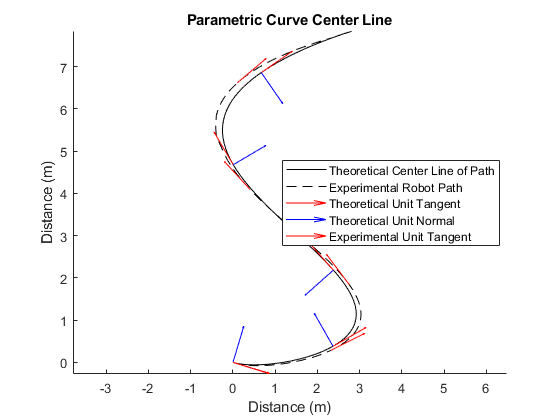

syms beta t

%set up symbolic equation center line
ri = 4*0.396*cos(2.65*(beta * t + 1.4));
rj = 4*-0.99*sin(beta * t+ 1.4);
rk = 4*0*t;
r=[ri,rj,rk];

%calculate symbolic derivative
dr=diff(r,t);

assume(beta,{'real','positive'})
assume(t,{'real','positive'})

%calculate symbolic T_hat and N_hat
T_hat=simplify(dr./norm(dr));
dT_hat=diff(T_hat,t);
N_hat=simplify(dT_hat/norm(dT_hat));

%these two lines are to make VL and VR always below 2m/s
%since u = beta*t, u still within the range [0, 3.2]
beta_num = .3;
t_num = linspace(0,3.2/beta_num,100); 

%initialize matrices for numerical r, T_hat, N_hat
r_num = zeros([100, 3]);
T_hat_num = zeros([100, 3]);
N_hat_num = zeros([100, 3]);

%find numerical values for r, T_hat, N_hat
for n=1:length(t_num)
    r_num(n,:)=double(subs(r, [beta, t], [beta_num, t_num(n)]));
    T_hat_num(n,:)=double(subs(T_hat,[beta, t], [beta_num, t_num(n)]));
    N_hat_num(n,:)=double(subs(N_hat, [beta, t], [beta_num, t_num(n)]));    
end

%have theoretical r to start at (0,0)
r_num(:, 1) = r_num(:, 1) + 1.3349;
r_num(:, 2) = r_num(:, 2) + 3.9024;

%initialize r and theta experimental matrices
r_exp = zeros(length(t_encoder), 2);
theta_exp = zeros(length(t_encoder), 1);
theta_exp(1) = -.3;

%calculate experimental r, theta based on equations:
%r(t + dt) = r(t) + v*T_hat*dt
%theta(t + dt) = theta(t) + w*dt
for n = 1:length(t_encoder) -1
    r_exp(n+1, 1) = r_exp(n,1) + v_encoder(n) * cos(theta_exp(n)) * (t_encoder(n+1) - t_encoder(n));
    r_exp(n+1, 2) = r_exp(n,2) + v_encoder(n) * sin(theta_exp(n)) * (t_encoder(n+1) - t_encoder(n));
    theta_exp(n+1) = theta_exp(n) + omega_encoder(n)*(t_encoder(n+1) - t_encoder(n));
end

%plot
figure(), clf
hold on
plot3(r_num(:,1),r_num(:,2),r_num(:,3), 'k')
plot(r_exp(:,1), r_exp(:,2), '--k')
axis equal
for n = 1:20:100
    quiver3(r_num(n,1),r_num(n,2),r_num(n,3),T_hat_num(n,1),T_hat_num(n,2),T_hat_num(n,3),'r') % plot the unit tangent
    quiver3(r_num(n,1),r_num(n,2),r_num(n,3),N_hat_num(n,1),N_hat_num(n,2),N_hat_num(n,3),'b') % plot the unit normal
    quiver(r_exp(n, 1), r_exp(n, 2), cos(theta_exp(n)), sin(theta_exp(n)), 'r')
end
title('Parametric Curve Center Line')
legend('Theoretical Center Line of Path', 'Experimental Robot Path', 'Theoretical Unit Tangent', 'Theoretical Unit Normal', 'Experimental Unit Tangent', 'Location', 'best')
xlabel('Distance (m)')
ylabel('Distance (m)')
hold off

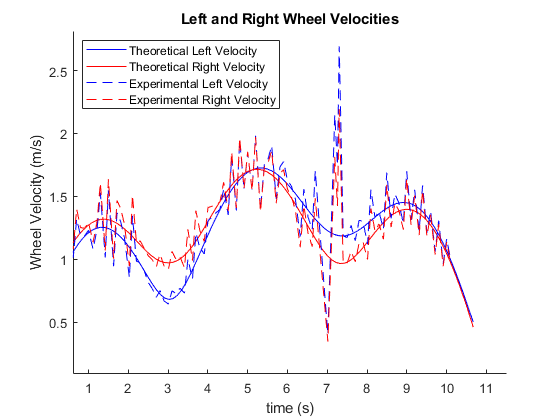

%36.2

%calculate theoretical symbolic left and right wheel velocities
syms omega d
omega = simplify(cross(T_hat, dT_hat));
v_R = simplify(norm(dr) + omega(3)*(d/2));
v_L = simplify(norm(dr) - omega(3)*(d/2));

%calculate values for theoretical left and right wheel velocities
v_left = zeros([1, 100]);
v_right = zeros([1, 100]);
for n = 1:length(t_num)
    v_left(n) = double(subs(v_L, [beta, t, d], [beta_num, t_num(n), d_num]));
    v_right(n) = double(subs(v_R, [beta, t, d], [beta_num, t_num(n), d_num]));
end

%plot
figure(), clf
hold on
plot(t_num,v_left, 'b')
plot(t_num,v_right, 'r')
plot(t_encoder,vL_encoder,'--b')
plot(t_encoder,vR_encoder,'--r')
title('Left and Right Wheel Velocities')
legend('Theoretical Left Velocity', 'Theoretical Right Velocity','Experimental Left Velocity','Experimental Right Velocity', 'Location', 'best')
xlabel('time (s)')
ylabel('Wheel Velocity (m/s)')
hold off

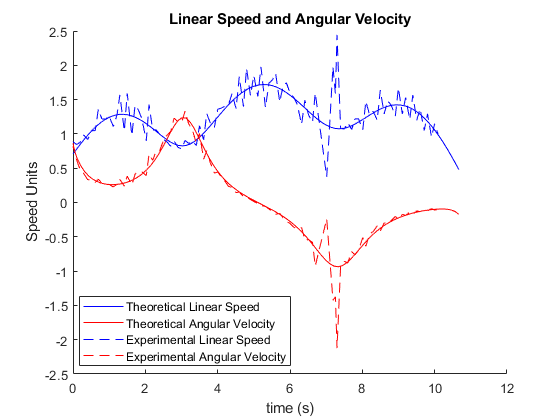

%36.3

%calculate symbolic theoretical linear speed and angular velocity
lin_speed = (v_R + v_L)/2;
ang_vel = (v_R - v_L)/d;

%calculate values for theoretical linear speed and angular velocity
lin_speed_num = zeros([1, 100]);
ang_vel_num = zeros([1, 100]);
for n = 1:length(t_num)
   lin_speed_num(n) = double(subs(lin_speed, [v_R, v_L, beta, t], [v_right(n),v_left(n), beta_num, t_num(n)]));
   ang_vel_num(n) = double(subs(ang_vel, [v_R, v_L, beta, t, d], [v_right(n), v_left(n), beta_num, t_num(n), d_num]));
end

%calculate experimental linear speed and angular velocity
lin_speed_encoder = (vR_encoder + vL_encoder)/2;
ang_vel_encoder = (vR_encoder - vL_encoder)/d_num;

%plot
figure(), clf
hold on
plot (t_num, lin_speed_num, 'b')
plot(t_num,ang_vel_num, 'r')
plot(t_encoder,lin_speed_encoder,'--b')
plot(t_encoder,ang_vel_encoder,'--r')
title('Linear Speed and Angular Velocity')
legend('Theoretical Linear Speed', 'Theoretical Angular Velocity','Experimental Linear Speed','Experimental Angular Velocity', 'Location', 'best')
xlabel('time (s)')
ylabel('Speed Units')
hold off